clear;clc

% load STs
STs_all_ZT11 = load('STs_err_all_ZT11.txt');
STs_all_ZT23 = load('STs_err_all_ZT23.txt');
STs_mono = load('STs_err_mono.txt');

% load S1s
S1s_all_ZT11 = load('S1s_err_all_ZT11.txt');
S1s_all_ZT23 = load('S1s_err_all_ZT23.txt');
S1s_mono = load('S1s_err_mono.txt');

% parameter names
par_name = ["\zeta", "\beta", "k_I", "\gamma", "\eta", "r", "a_{MI}", "a_{NI}", "a_{KI}", "a_{TI}", ...
        "c_{IL1b-Mono}", "c_{IL1b-N}", "c_{CCL2-Mono}", "c_{CXCL5-N}", "c_{M-IL1b}", "c_{I-IL1b}", ...
        "c_{M-IL10}", "c_{M-CCL2}", "c_{I-CCL2}", "c_{N-CXCL5}", "c_{I-CXCL5}", "c_{I-K}", "c_{M-T)", ...
        "K_V", "K_{IL1b-Mono}", "K_{IL1b-N}", "K_{CCL2-Mono}", "K_{CXCL5-N}", "K_{IL10-IL1b}", "K_{IL10-CCL2}", "K_{IL10-CXCL5}", ...
        "K_{I-K}", "K_T", "K_{M-T}", "n_{CCL2-Mono}", "n_{CXCL5-N}", "n_{I-K}", "n_{M-T}", ...
        "d_I", "d_V", "d_{Vs}", "d_{Mono}", "d_N", "d_{IL1b}", "d_{IL10}", "d_{CCL2}", "d_{CXCL5}", "d_K", "d_T", "b_H", "b_K", ...
        "K_{BMAL1-IL1b}", "K_{BMAL1-CCL2}", "K_{REV-V}", "K_{REV-IL10}", ...
        "K_{REV-CCL2}", "K_{REV-CXCL5}", "c_{IL1b-REV}", "K_{IL1b-REV}", "n_{IL1b-REV}"];

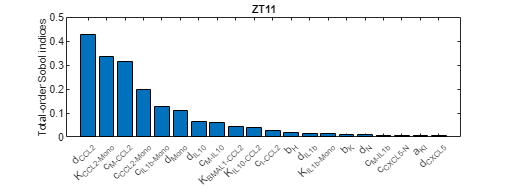

% plot STs for ZT11
[~, sorted_idx_11] = sort(STs_all_ZT11, 'descend');

figure;
set(gca, 'Fontsize',8, 'FontName', 'Arial'); box on; hold on;
bar(STs_all_ZT11(sorted_idx_11(1:20)));
xticks(1:20);
xticklabels(par_name(sorted_idx_11(1:20)));
ylabel('Total-order Sobol indices', 'Fontsize',8, 'FontName', 'Arial');
title('ZT11', 'Fontsize',8, 'FontName', 'Arial');
set(gcf, 'unit', 'centimeters', 'position', [10 5 13.46 5.05]);
hold off;

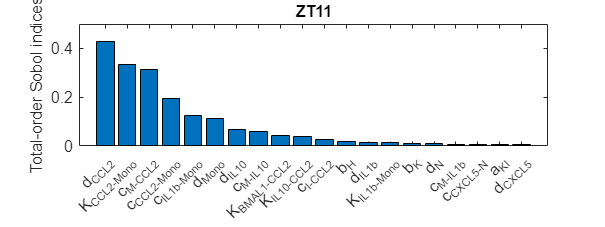


figure;
set(gca, 'Fontsize',12, 'FontName', 'Arial'); box on; hold on;
bar(STs_all_ZT11(sorted_idx_11(1:20)));
xticks(1:20);
xticklabels(par_name(sorted_idx_11(1:20)));
ylabel('Total-order Sobol indices', 'Fontsize',12, 'FontName', 'Arial');
title('ZT11', 'Fontsize',12, 'FontName', 'Arial');
set(gcf, 'unit', 'centimeters', 'position', [10 5 16 6]);
hold off;

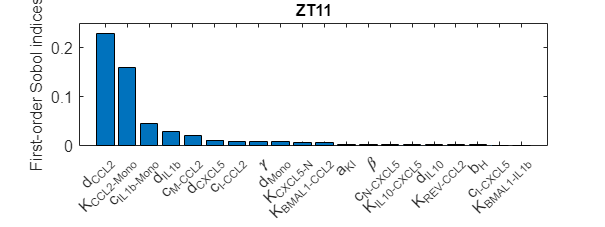

% plot S1s for ZT11
[~, sorted_idx_11] = sort(S1s_all_ZT11, 'descend');

figure;
set(gca, 'Fontsize',12, 'FontName', 'Arial'); box on; hold on;
bar(S1s_all_ZT11(sorted_idx_11(1:20)));
xticks(1:20);
xticklabels(par_name(sorted_idx_11(1:20)));
ylabel('First-order Sobol indices', 'Fontsize',12, 'FontName', 'Arial');
title('ZT11', 'Fontsize',12, 'FontName', 'Arial');
set(gcf, 'unit', 'centimeters', 'position', [10 5 16 6]);
hold off;

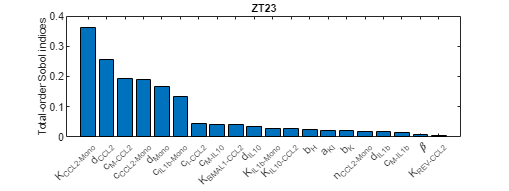

% plot STs for ZT23
[~, sorted_idx_23] = sort(STs_all_ZT23, 'descend');

figure;
set(gca, 'Fontsize',8, 'FontName', 'Arial'); box on; hold on;
bar(STs_all_ZT23(sorted_idx_23(1:20)));
xticks(1:20);
xticklabels(par_name(sorted_idx_23(1:20)));
ylabel('Total-order Sobol indices', 'Fontsize',8, 'FontName', 'Arial');
title('ZT23', 'Fontsize',8, 'FontName', 'Arial');
set(gcf, 'unit', 'centimeters', 'position', [10 5 13.46 5.05]);
hold off;

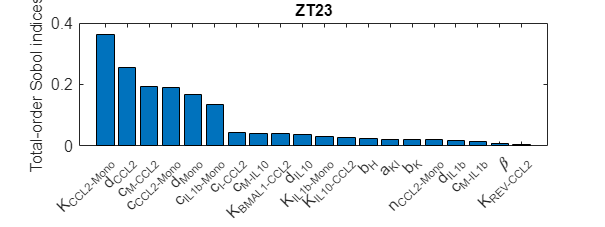


figure;
set(gca, 'Fontsize',12, 'FontName', 'Arial'); box on; hold on;
bar(STs_all_ZT23(sorted_idx_23(1:20)));
xticks(1:20);
xticklabels(par_name(sorted_idx_23(1:20)));
ylabel('Total-order Sobol indices', 'Fontsize',12, 'FontName', 'Arial');
title('ZT23', 'Fontsize',12, 'FontName', 'Arial');
set(gcf, 'unit', 'centimeters', 'position', [10 5 16 6]);
hold off;

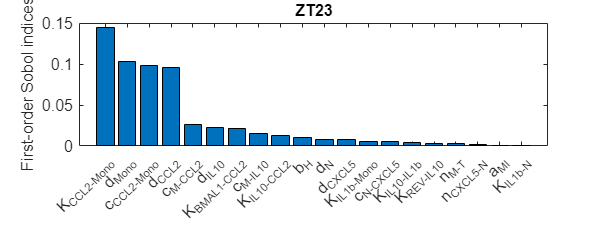

% plot S1s for ZT23
[~, sorted_idx_23] = sort(S1s_all_ZT23, 'descend');

figure;
set(gca, 'Fontsize',12, 'FontName', 'Arial'); box on; hold on;
bar(S1s_all_ZT23(sorted_idx_23(1:20)));
xticks(1:20);
xticklabels(par_name(sorted_idx_23(1:20)));
ylabel('First-order Sobol indices', 'Fontsize',12, 'FontName', 'Arial');
title('ZT23', 'Fontsize',12, 'FontName', 'Arial');
set(gcf, 'unit', 'centimeters', 'position', [10 5 16 6]);
hold off;

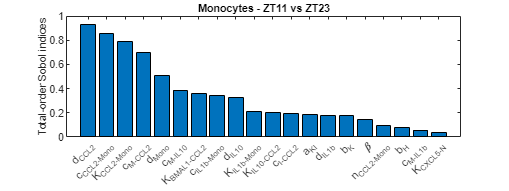

% plot STs for ZT11-ZT23
[~, sorted_idx_mono] = sort(STs_mono, 'descend');

figure;
set(gca, 'Fontsize',8, 'FontName', 'Arial'); box on; hold on;
bar(STs_mono(sorted_idx_mono(1:20)));
xticks(1:20);
xticklabels(par_name(sorted_idx_mono(1:20)));
ylabel('Total-order Sobol indices', 'Fontsize',8, 'FontName', 'Arial');
title('Monocytes - ZT11 vs ZT23', 'Fontsize',8, 'FontName', 'Arial');
set(gcf, 'unit', 'centimeters', 'position', [10 5 13.46 5.05]);
hold off;

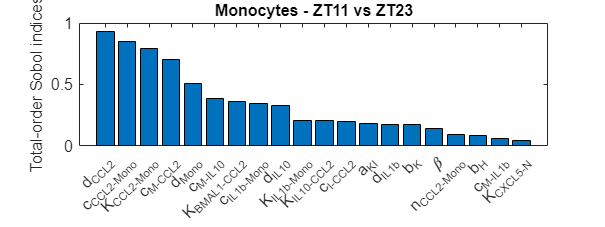


figure;
set(gca, 'Fontsize',12, 'FontName', 'Arial'); box on; hold on;
bar(STs_mono(sorted_idx_mono(1:20)));
xticks(1:20);
xticklabels(par_name(sorted_idx_mono(1:20)));
ylabel('Total-order Sobol indices', 'Fontsize',12, 'FontName', 'Arial');
title('Monocytes - ZT11 vs ZT23', 'Fontsize',12, 'FontName', 'Arial');
set(gcf, 'unit', 'centimeters', 'position', [10 5 16 6]);
hold off;

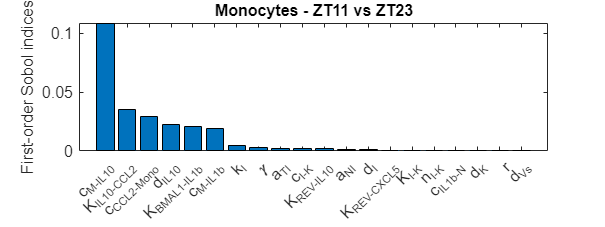

% plot S1s for ZT11-ZT23
[~, sorted_idx_mono] = sort(S1s_mono, 'descend');

figure;
set(gca, 'Fontsize',12, 'FontName', 'Arial'); box on; hold on;
bar(S1s_mono(sorted_idx_mono(1:20)));
xticks(1:20);
xticklabels(par_name(sorted_idx_mono(1:20)));
ylabel('First-order Sobol indices', 'Fontsize',12, 'FontName', 'Arial');
title('Monocytes - ZT11 vs ZT23', 'Fontsize',12, 'FontName', 'Arial');
set(gcf, 'unit', 'centimeters', 'position', [10 5 16 6]);
hold off;